# Visualizing Multidimensional Data

So far in this module you've learned about some common statistical distributions as well as techniques for describing a variable's distribution through histograms and descriptive statistics. By visualizing two or more variables at a time, however, you can better understand and identify relationships between variables and groups of observations in your data. In this script, you'll first see how some common distributions generalize to multiple dimensions while learning how to visualize two or more variables using *multidimensional* visualizations.

## Introducción

El uso de visualizaciones apoyará la interpretación y explicación de los resultados, no solo los obtenidos de un análisis exploratorio, también es de utilidad para modelos predictivos o de agrupamiento (clasificación)

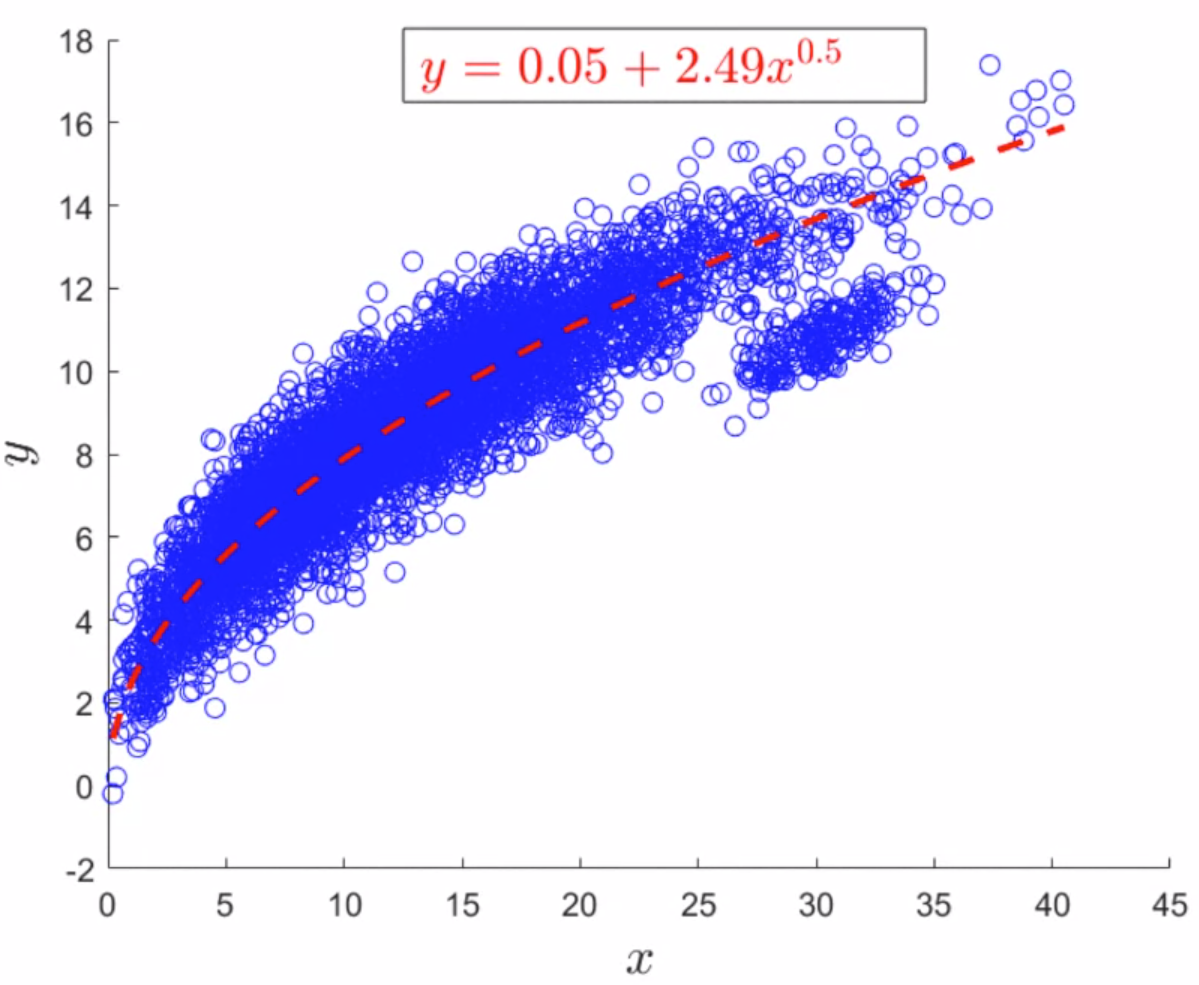 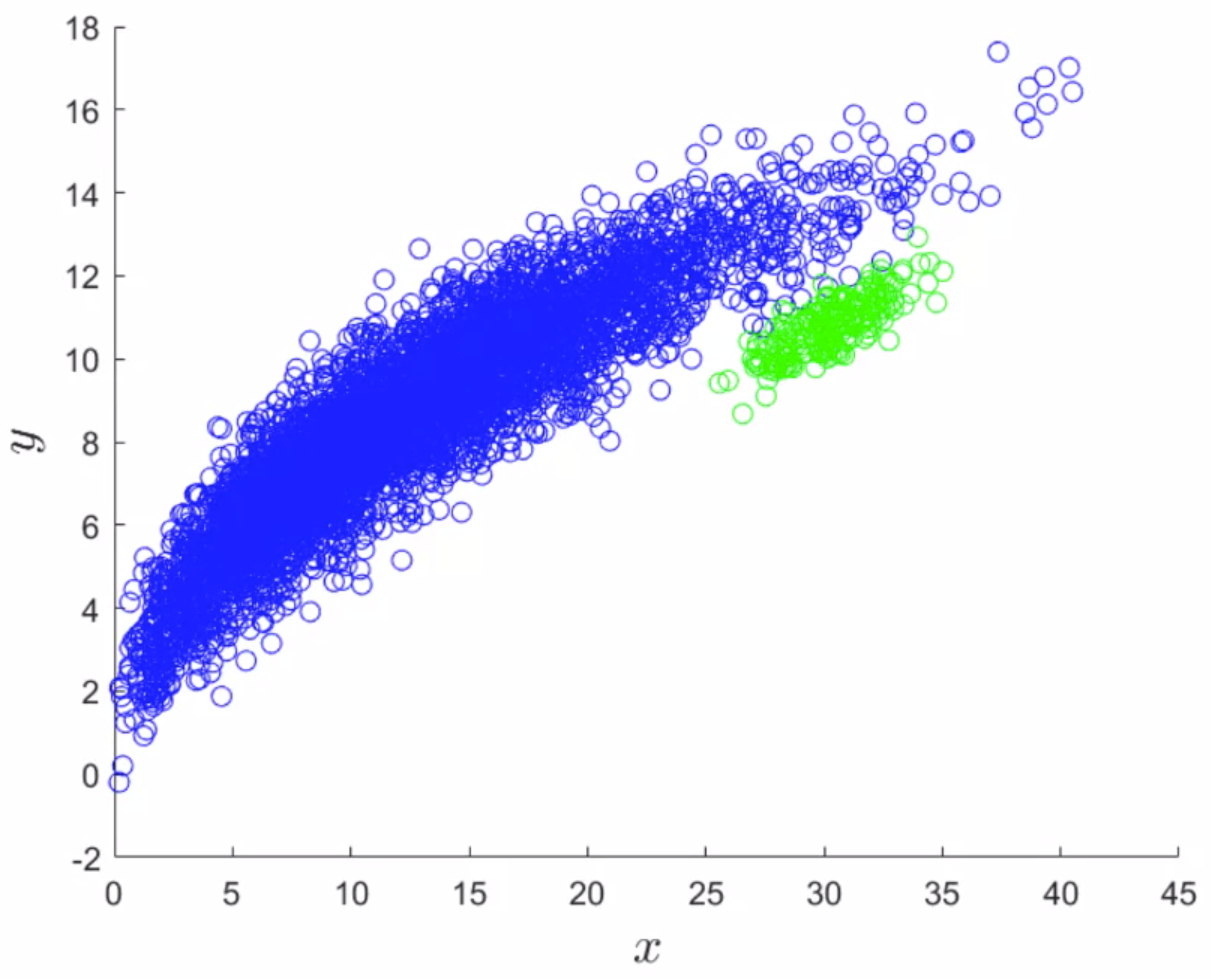

## Distribución uniforme 2D

Es posible comparar 2 histogramas por medio de un gráfico 3D, en el código se presentan controles para ajustar las distribuciones de tipo uniforme  y observar los cambios. La función `histogram2` realiza esta visualización

m = 100; % Cantidad de datos
xmin =-6.75; % valor mínimo de X
ymin =-3.75; % valor mínimo de Y
xmax =5.9; % valor máximo de X
ymax =5.5; % valor máximo de Y
X = rand([m,2]).*[xmax-xmin, ymax-ymin]+[xmin,ymin]; % generate X and Y
% Generate and label the 2D histogram
histogram2(X(:,1),X(:,2),'NumBins',7,...
                         'XBinLimits',[xmin,xmax],...
                         'YBinLimits',[ymin,ymax]);
xlabel('$X$','Interpreter','latex'); 
ylabel('$Y$','Interpreter','latex'); 
zlabel('Count');
xlim([-10 10]); ylim([-10 10]);

**Nota: **El control rotatorio puede ser de utilidad  

¿Como afectan los parámetros la apariencia del histograma? ¿Que combinación es más fácil de interpretar como 2 distribuciones uniformes? ¿Cual lo dificulta?

## Distribución normal 2D

Con la función binscatter, es posible generar una nube de puntos que relacione 2 variables, en la cual se cambia la altura de un gráfico 3D por tonalidades y mantener así la figura en 2D

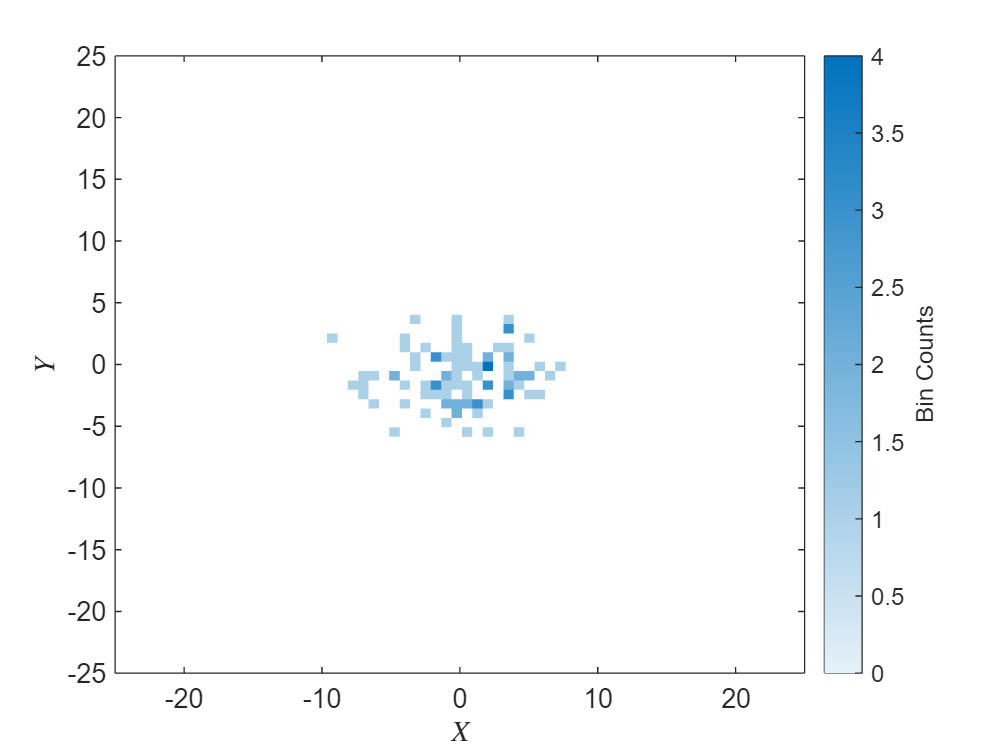

m = 100; % # Cantidad de puntos
mux =-0.25; % media X
muy =-1; % media Y
sigmax =3.75; % std-X
sigmay =2; % std-Y
bins = 70; % # bins
c = 0; % coeficiente de correlación
X = mvnrnd([mux,muy], [sigmax^2, c*(sigmax*sigmay); c*(sigmax*sigmay), sigmay^2], m);
binscatter(X(:,1),X(:,2),bins);
xlim([-25 25]); ylim([-25 25]);
xlabel('$X$','Interpreter','latex'); 
ylabel('$Y$','Interpreter','latex');

## Combinación de distribuciones

Es común que dos variables presenten distribuciones distintas, en esos casos es posible añadir su histograma al gráfico para evidenciar esa diferencia. La función a utilizar es `scatterhistogram`

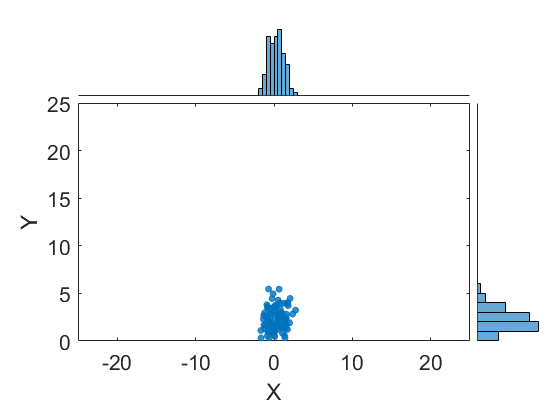

m = 100; % # cantidad de datos
mu =0; % media distribución normal
sigma =1; % std distribución normal
b =2; % sesgo distribución Rayleigh
x = random('Normal',mu,sigma,[m,1]); % Generamos fdp X
y = random('Rayleigh',b,[m,1]); % generamos fdp Y
scatterhistogram(x,y,"XLabel","X","YLabel","Y",'FontSize',16,...
                     'MarkerSize',20,... % tamaño marcador
                     'MarkerAlpha',0.8,... % transparencia marcador
                     'MarkerFilled',"on",... % marcadores sólidos o huecos
                     'HistogramDisplayStyle',"bar"); % Tipo de histograma
xlim([-25 25]); 
ylim([0 25]);

## Visualizando variables continuas

En los siguientes ejemplos veremos opciones para graficar multiples variables o con distintos tipos de datos

Se utilizará le dataset de pacientes (patients.mat) para ejemplificar multiples variables de distintos tipos

Realicemos una nube de puntos y sus histogramas para la variable Peso y Altura

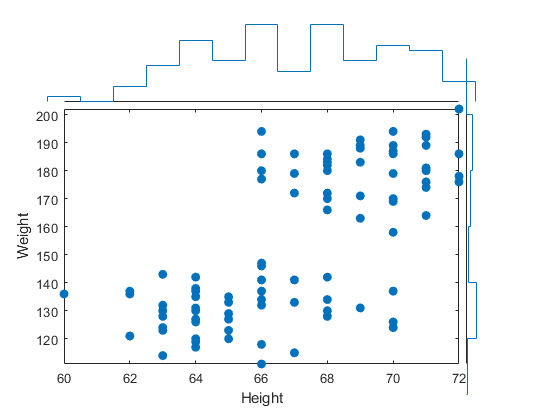

load patients
tbl = table(Weight,Height,Age,Systolic,Diastolic,Gender,Smoker,Location);
tbl.SelfAssessedHealthStatus = categorical(SelfAssessedHealthStatus,{'Excellent','Good','Fair','Poor'});
clearvars -except tbl
scatterhistogram(tbl,'Height','Weight');

La nube de puntos indica una correlación positiva. Además los datos parecen separados por dos grupos, añadir una variable mas que agrupe esta información sería de utilidad

### Añadiendo una variable de agrupamiento a una nube de puntos con histograma

Para determinar si una de las variables discretas es responsable por el agrupamiento, podemos especificar una de estas variables dentro de una nube de puntos con histograma, en el código presentado abajo se muestran estas opciones, los controles permiten cambiar entre variables categóricas para agrupar asi los datos

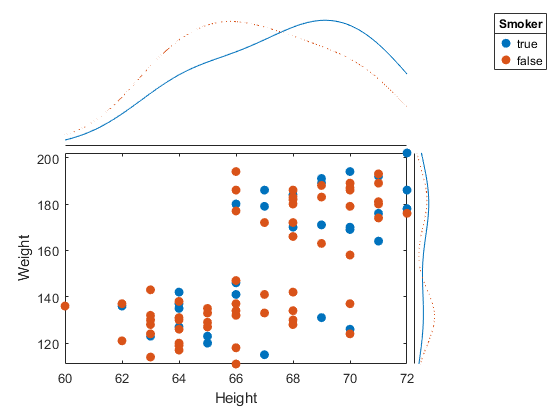

scatterhistogram(tbl,'Height','Weight',...
                    'GroupVariable','Smoker',...
                    'LegendVisible','on',...
                    'ScatterPlotProportion',0.6,...
                    'HistogramDisplayStyle',"smooth");

¿Que variable separa mejor la nube de puntos generada por la altura y peso?

## Visualizando variables discretas (categóricas)

Los Heatmap son de utilidad para este tipo de variables, asi podemos realizar conteos con las combinaciones que presenten 2 variables categóricas, la cantidad se visualiza añadiendo color al gráfico, así la intensidad corresponderá a la cantidad presentada en cada cuadro

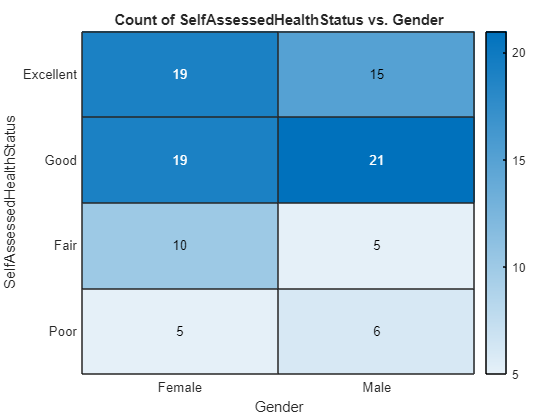

heatmap(tbl,'Gender','SelfAssessedHealthStatus');

### Uso de variables continuas en heat map

Es posible añadir información de una variable continua a un heat map de variables discretas especificando el parámetro "colorVariable" y relacionándolo con la variable continua a utilizar. En este caso en lugar de obtener un conteo, obtenemos un valor estadístico para cada grupo o cuadro, y la intensidad del color se relaciona con el valor de cada cuadro. Es una forma de visualizar las tablas generadas por la función `groupsummary`

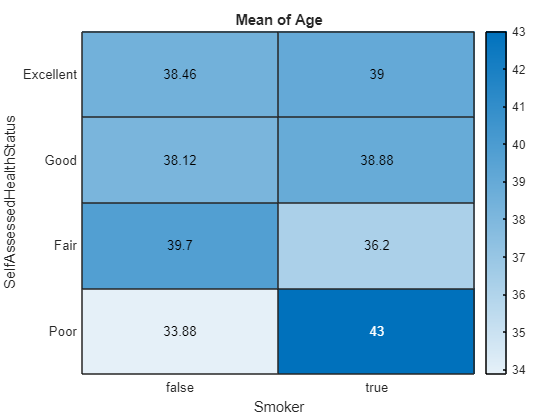

heatmap(tbl,'Smoker','SelfAssessedHealthStatus',...
            'ColorVariable',"Age",...
            'ColorMethod', "mean");                                               

como desventaja, este tipo de gráficos no presenta el número de observaciones, por lo que las conclusiones obtenidas solamente con este tipo de diagramas puede estar sesgada

## Visualizando datasets de múltiples dimensiones

Al realizar ploteos o gráficas de 2 variables puede ser tedioso si debe ralizarse esta comparación un dataset mas amplio y hay que explorar todas las posibles combinaciones. con la función` gplotmatrix`, puede graficarse un dataset, mediante la combinación de nubes de puntos para 2 variables

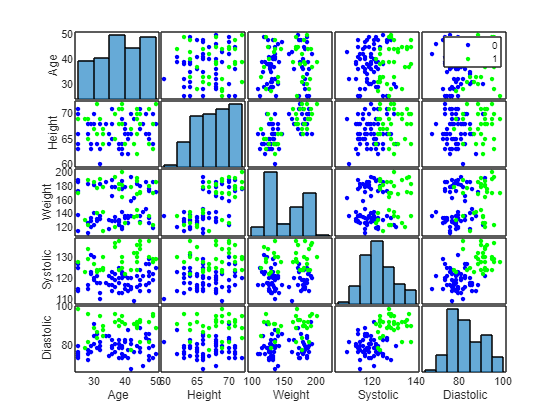

contvars = ["Age", "Height", "Weight", "Systolic", "Diastolic"];
X = tbl{:,contvars};
gplotmatrix(X,[],tbl.Smoker,[],[],[],[],'hist',contvars)

Las variables categóricas pueden ser seleccionadas para agrupar los datos y así separar por colores. También puede elegrise distintos gráficos para las variables individuales y observar las distribuciones a combinar

### Creando una gráfica paralela

Esta función permite visualizar las variables continuas de un dataset al agregar un eje par acada variable y uniendo los puntos de cada observación. Puede personalizarse esta gráfica para controlar los colores (agrupamiento) propiedades de las líneas como grosor o transparencia o normalizar los ejes bajo distintos métodos

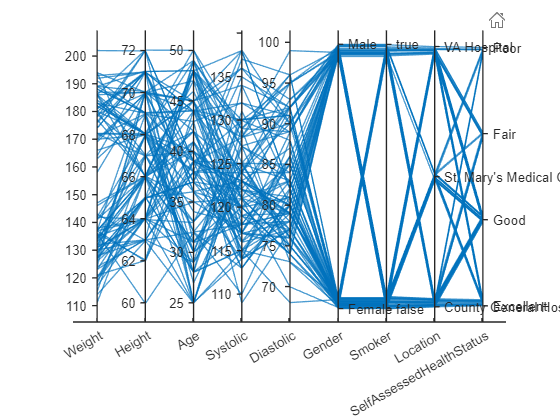

parallelplot(tbl);

### Personalizar gráfica paralela

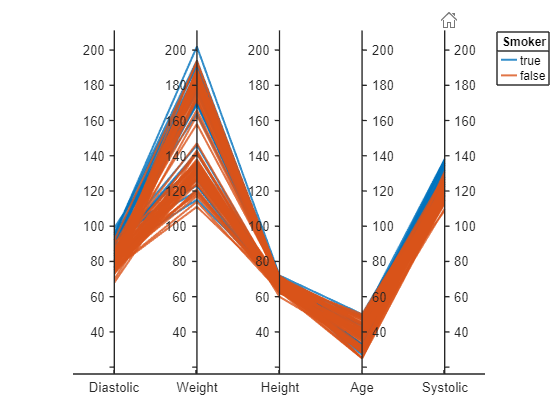

parallelplot(tbl,"CoordinateVariables",contvars(randperm(length(contvars))),...
                 'GroupVariable','Smoker',...
                 'DataNormalization',"none",...
                 "LineAlpha",0.8,...
                 "LineWidth",1.5);